# 1.2.1. Основные типы данных

**Лекция**

## Краткий обзор основных типов данных

Структура основных типов данных, используемых в среде MATLAB представлена на схеме:

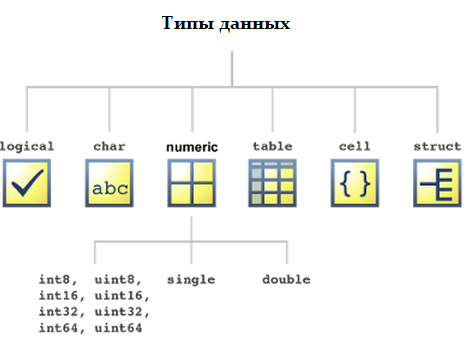

    **●   Численный **тип (numerical) данных используется для хранения целых чисел (`int, uint`) и чисел с плавающей точкой (`single, double`). С этим типом данных мы имели дело с самого начала данного курса. 

    **●   Символьные **типы данных используются для хранения символов, строк и текста. Тип `char` позволяет хранить символы по отдельности и формировать массивы (вектора-строки/столбцы, матрицы) из них. тип `string` позволяет хранить слова целиком и более предпочтителен для работы с текстом

    **●   **Данные **логического** типа (logical) могут иметь только 2 значения: `true` и `false.` Область их применения достаточно широка, этот тип будет подробно рассмотрен  в лекции 1.2.10 "Фильтрация данных". 

    **●   Структуры** (struct) в MATLAB могут хранить в себе предварительно названные наборы данных разного типа, к которым можно обращаться через их названия. 

    **●   Массивы ячеек **(cell, cell array) позволяют также как и структуры хранить данные разного типа, однако в отличие от структуры, элементы массива ячеек проиндексированны как элементы матрицы. К ним можно обращаться по их порядковому номеру, в отличие от обращения по названию в случае структур. 

    **●   Таблицы** (tables) позволяет упорядоченно хранить данные разных типов, обрабатывать и упорядочивать массивы информации.

## Численные типы: целочисленные и с плавающей точкой

С числами с плавающей точкой, в частности с типом `double` мы уже сталкивались. Числа типа `double` не могут занимать места больше 8 байт (64 бит), а числа типа `single` больше 4 байт (32 бит). 

clear
x = 1.45e-98    % число с плавающей запятой

x = 1.4500e-98

Целочисленные типы могут быть как знаковыми (signed), так и беззнаковыми (unsigned). Перечень целочисленных типов представлен в таблице:

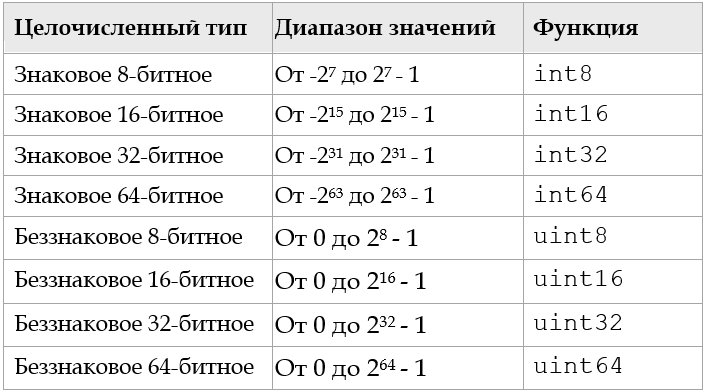

При обработке целочисленных типов память используется более эффективно, чем при обработке чисел с плавающей точкой. Таким образом, использование целочисленных типов может ускорить вычисления.

y = int64(-589324077574) % целочисленный тип

y = int64
-589324077574

Также возможно преобразовывать один числовой тип в другой:

z = double(y)   % Преобразование целого типа в double. 

z = -5.8932e+11

int64(z)    % Преобразования double в int64

ans = int64
-589324077574

## Символьные типы: символы (char) и строки (string)

Символьные переменные можно создавать по их номеру в таблице кодировки ASCII:

ch1 = char(0065)   % Номер символа в ASCII

ch1 = 'A'

Символьные переменные можно задавать напрямую:

ch2 = '?'        

ch2 = '?'

Массив (вектор-строку) символов можно задать напрямую, записывая их набор в одинарные кавычки, а доступ к каждому символу осуществляется также, как и для числовых векторов:

ch3 = 'Где твоя одежда '  % массив символов

ch3 = 'Где твоя одежда '

ch3(5)      % доступ к элементу символьного массива 

ans = 'т'

Для символьных векторов также справедлива операция конкатенации:

ch4 = [ch3, ch2, ' ', ch1, ch2, ' То-то же.', ' (1)']  % конкатенация символьных переменных

ch4 = 'Где твоя одежда ? A? То-то же. (1)'

Чтобы создать строку вручную, требуется ввести её содержимое в двойные кавычки

str1 = "Falcon "      % строки создаются с помощью двойных кавычек

str1 = "Falcon "

Операция сложения строк присоединяет одну к другой следующим образом:

str2 = "Heavy ";
str3 = str1 + str2 + "- самая современная ракета-носитель"     % сложение строчных переменных

str3 = "Falcon Heavy - самая современная ракета-носитель"

Из строк можно создавать двумерные массивы, а доступ к ним аналогичен доступу к элементам числовых матриц:

str4 = ["Байконур", "Плесецк", "Восточный";
        "Мыс Канаверал", "Центр Кеннеди", "Ванденберг"]

str4 = 2×3 string array
    "Байконур"         "Плесецк"          "Восточный" 
    "Мыс Канаверал"    "Центр Кеннеди"    "Ванденберг"


str4(2,end)     % доступ к элементам массива строк

ans = "Ванденберг"

Для строчных массивов справедлива операция конкатенации: 

[str4,[str1; str2]] % конкатенация массива строк

ans = 2×4 string array
    "Байконур"         "Плесецк"          "Восточный"     "Falcon "
    "Мыс Канаверал"    "Центр Кеннеди"    "Ванденберг"    "Heavy " 


Массив строк можно складывать с одиночной строкой. Операция аналогична сложению числа и матрицы:

"Космодром " + str4

ans = 2×3 string array
    "Космодром Байконур"         "Космодром Плесецк"          "Космодром Восточный" 
    "Космодром Мыс Канаверал"    "Космодром Центр Кеннеди"    "Космодром Ванденберг"


Рассмотрены лишь основные команды для работы со строками. Для более детального описания строк введите в командной строке:

## Логический тип данных (logical): введение

Работа с данными типа `logical `более подробно описана в главе 1.2.10 "Фильтрация данных". 

Массив из логических переменных можно задавать вручную, и у них, как было отмечено выше, могут быть только 2 значения: `true` и `false` (логические "1" и "0" соответственно):

lg1 = [false, true, true, false]    % создание логического массива вручную

lg1 = 1×4 logical array
   0   1   1   0


Логические переменные являются результатом арифметических сравнений:

lg1_1 = [3<5, 3>5, 4>=4, 6<=2, 6==6,  7~=7 ]    % основные операции сравнения

lg1_1 = 1×6 logical array
   1   0   1   0   1   0


К логическим переменным применимы операции логического И, ИЛИ, НЕ:

[   true & false, true & true, false & false;   % логическое И
    true | false, true | true, false | false;   % логическое ИЛИ
    ~true, ~false, xor(true,false)]             % логическое отрицание и исключающее И

ans = 3×3 logical array
   0   1   0
   1   1   0
   0   1   1


С помощью логических векторов можно осуществлять индексацию и выбор желаемых компонент:

num1 = [1, 3, 8, 4];
num1(lg1)   % индексация с помощью логического массива 

ans =      3     8


Количество компонент вектора, удовлетворяющие заданному условию, определяются следующим образом:

1) Определяется соответствующий логический массив:

lg2 = num1>3  % логический массив для вектора по заданному условию

lg2 = 1×4 logical array
   0   0   1   1


2) С помощью функции `nnz` определяется количество ненулевых элементов:

nnz(lg2)    % считает количество ненулевых элементов

ans = 2

Больше информации про логические переменные и особенности работы с ними можно посмотреть, запуская с командной строки следующую команду:

## Структуры в MATLAB

Данные разных типов можно хранить в структурах в определяемых и называемых полях. Основной принцип работы со структурами продемонстрируем на структуре, предложенной ниже: 

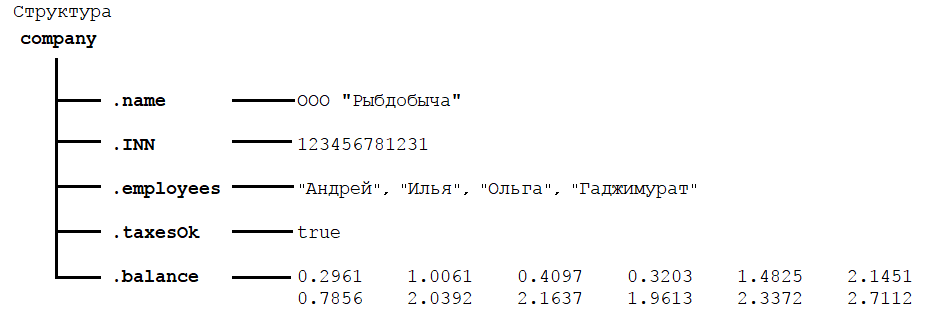

Структура company имеет поля:  `name` - символьный массив, `INN` - натуральное число, `employees` - массив строк, `taxesOk` - логическая переменная и `balance` - числовая матрица размерами 2х6. Синтаксис создания выглядит следующим образом: 

company.name = 'ООО "Рыбдобыча"';
company.INN = uint64(randi([0, 10^14]));
company.employees = ["Андрей", "Илья", "Ольга", "Гаджимурат"];
company.taxesOk = true;
company.balance  = 3*rand(2,6);
company

company = struct with fields:
         name: 'ООО "Рыбдобыча"'
          INN: 64431813019369
    employees: ["Андрей"    "Илья"    "Ольга"    "Гаджимурат"]
      taxesOk: 1
      balance: [2×6 double]


Синтаксис доступа к элементам структуры следующий: `ИмяСтруктуры.ИмяПоля`. Пример:

saldo = sum(company.balance(1,:)-company.balance(2,:))

saldo = -0.1515

Больше информации про структуры и работу с ними можно узнат в документации:

## Ячейки и массивы ячеек (cell)

c1 = {11; 22; 33}

c1 = 3×1 cell array
    {[11]}
    {[22]}
    {[33]}


c2 = {1, 2, 3; 'Текст', rand(3,4), c1} % создание массива ячеек

c2 = 2×3 cell array
    {[    1]}    {[       2]}    {[     3]}
    {'Текст'}    {3×4 double}    {3×1 cell}


celldisp(c2)

 
c2{1,1} =
 
     1

 
 
c2{2,1} =
 
Текст
 
 
c2{1,2} =
 
     2

 
 
c2{2,2} =
 
    0.2305    0.2259    0.4357    0.4302
    0.8443    0.1707    0.3111    0.1848
    0.1948    0.2277    0.9234    0.9049

 
 
c2{1,3} =
 
     3

 
 
c2{2,3}{1} =
 
    11

 
 
c2{2,3}{2} =
 
    22

 
 
c2{2,3}{3} =
 
    33

 


c3 = cell(4,3)   % пустой массив ячеек заданной размерности

c3 = 4×3 cell array
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}


[c2;c3]         % конкатенация ячеек

ans = 6×3 cell array
    {[       1]}    {[       2]}    {[       3]}
    {'Текст'   }    {3×4 double}    {3×1 cell  }
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}


c2{2,3}         % доступ к содержимому ячейки 

ans = 3×1 cell array
    {[11]}
    {[22]}
    {[33]}


c2(2,3)         % непосредственно ячейка

ans = 1×1 cell array
    {3×1 cell}


c2(2,:)         % выделенный вектор ячеек

ans = 1×3 cell array
    {'Текст'}    {3×4 double}    {3×1 cell}


c2{2,:}         % содержание всех ячеек в выбранном векторе

ans = 'Текст'

ans =     0.2305    0.2259    0.4357    0.4302
    0.8443    0.1707    0.3111    0.1848
    0.1948    0.2277    0.9234    0.9049


ans = 3×1 cell array
    {[11]}
    {[22]}
    {[33]}


## Таблицы (table)

arr1 = magic(4);
table1 = array2table(arr1,'VariableNames',{'A','B','C','D'})    % таблица из матрицы чисел

table1 = 4×4 table
    A     B     C     D 
    __    __    __    __

    16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


countries = {"США"; "Россия"; "Китай"; "ЕС"; "Япония"; "Индия"; "Австралия" };
LaunchData = {  2	6	21	29	29	0	0;
                11	5	3	19	17	1	1;
                10	8	0	18	16	1	1;
                3	0	8	11	11	0	0;
                5	2	0	7	6	1	0;
                5	0	0	5	4	1	0;
                0	0	1	1	0	1	0};
LaunchTable1 = cell2table([countries,LaunchData])       % таблица из массива ячеек 

LaunchTable1 = 7×8 table
       Var1        Var2    Var3    Var4    Var5    Var6    Var7    Var8
    ___________    ____    ____    ____    ____    ____    ____    ____

    "США"            2      6       21      29      29      0       0  
    "Россия"        11      5        3      19      17      1       1  
    "Китай"         10      8        0      18      16      1       1  
    "ЕС"             3      0        8      11      11      0       0  
    "Япония"         5      2        0       7       6      1       0  
    "Индия"          5      0        0       5       4      1       0  
    "Австралия"      0      0        1       1       0      1       0  


LaunchTable1.Properties.VariableNames = ... % Задаём имена каждому столбцу
    {'Country','Civil','Military','Commerc','Total','Succeed','Failed','Partial'} 

LaunchTable1 = 7×8 table
      Country      Civil    Military    Commerc    Total    Succeed    Failed    Partial
    ___________    _____    ________    _______    _____    _______    ______    _______

    "США"            2         6          21        29        29         0          0   
    "Россия"        11         5           3        19        17         1          1   
    "Китай"         10         8           0        18        16         1          1   
    "ЕС"             3         0           8        11        11         0          0   
    "Япония"         5         2           0         7         6         1          0   
    "Индия"          5         0           0         5         4         1     

byMilitary = sortrows(LaunchTable1,'Military','descend')    % Сортировка по столбцу Military, по убыванию

byMilitary = 7×8 table
      Country      Civil    Military    Commerc    Total    Succeed    Failed    Partial
    ___________    _____    ________    _______    _____    _______    ______    _______

    "Китай"         10         8           0        18        16         1          1   
    "США"            2         6          21        29        29         0          0   
    "Россия"        11         5           3        19        17         1          1   
    "Япония"         5         2           0         7         6         1          0   
    "ЕС"             3         0           8        11        11         0          0   
    "Индия"          5         0           0         5         4         1       

Top3Launches = LaunchTable1(1:3,[1,5:6])    % Вычленение требуемых данных

Top3Launches = 3×3 table
    Country     Total    Succeed
    ________    _____    _______

    "США"        29        29   
    "Россия"     19        17   
    "Китай"      18        16   


CivilPercentage = round(100*LaunchTable1.Civil./LaunchTable1{:,5})  % 2 способа доступа к стобцам таблицы

CivilPercentage =      7
    58
    56
    27
    71
   100
     0


MilPercentage = round(100*LaunchTable1.Military./LaunchTable1.Total);
CommercPercentage = round(100*LaunchTable1.Commerc./LaunchTable1.Total);

LaunchTable1.CivilRate = CivilPercentage;       % 1 способ добавления столбцов

LaunchTable1{:, 'MilRate'} = MilPercentage;     % 2 способ добавления столбцов

LaunchTable1{:,end+1} = CommercPercentage;      % 3 способ добавления столбцов
LaunchTable1.Properties.VariableNames(end) = {'CommercRate'}

LaunchTable1 = 7×11 table
      Country      Civil    Military    Commerc    Total    Succeed    Failed    Partial    CivilRate    MilRate    CommercRate
    ___________    _____    ________    _______    _____    _______    ______    _______    _________    _______    ___________

    "США"            2         6          21        29        29         0          0            7         21            72    
    "Россия"        11         5           3        19        17         1          1           58         26            16    
    "Китай"         10         8           0        18        16         1          1  

LaunchTable2 = LaunchTable1(1:3, {'Country', 'Total', 'Military','MilRate'})

LaunchTable2 = 3×4 table
    Country     Total    Military    MilRate
    ________    _____    ________    _______

    "США"        29         6          21   
    "Россия"     19         5          26   
    "Китай"      18         8          44   


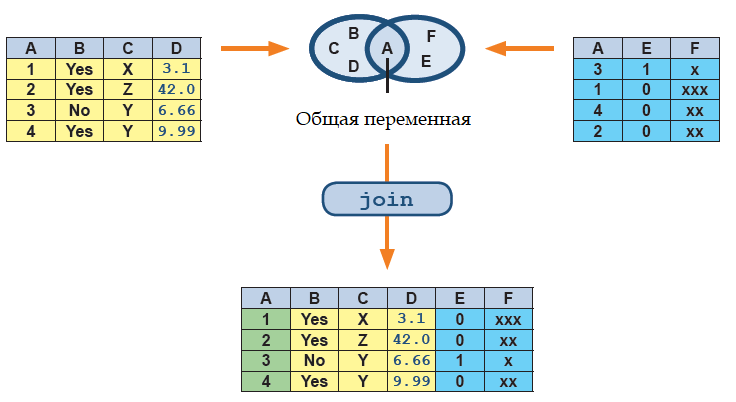

join(Top3Launches,LaunchTable2)

ans = 3×5 table
    Country     Total    Succeed    Military    MilRate
    ________    _____    _______    ________    _______

    "США"        29        29          6          21   
    "Россия"     19        17          5          26   
    "Китай"      18        16          8          44   


## Описание даты и времени 

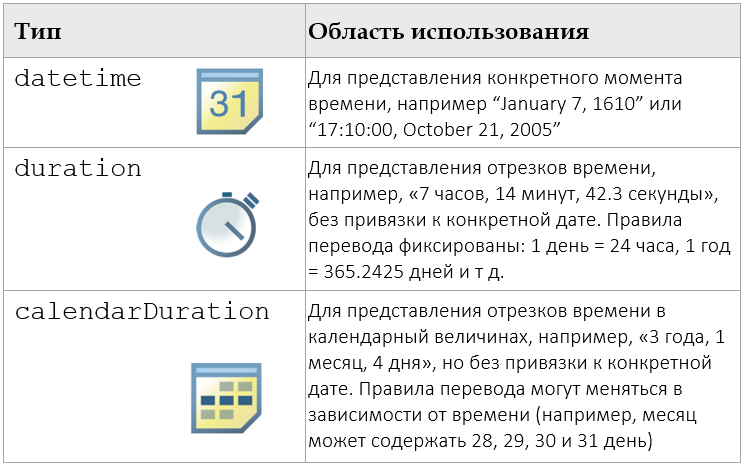

plane1 = datetime(2001,9,11, 8,46,26)

plane1 = datetime
   11-Sep-2001 08:46:26


plane1.Format = 'hh:mm:ss dd.MMM.yyyy'

plane1 = datetime
   08:46:26 11.Sep.2001


plane2 = datetime(2001,9,11, 9,2,59);
dplane = plane2 - plane1        % в формате duration

dplane = duration
   00:16:33


WW1 = datetime(1914,07,28);
WW2 = datetime(1939,09,01);
round([years(WW2-WW1), days(WW2-WW1), hours(WW2-WW1), minutes(WW2-WW1), seconds(WW2-WW1)])  % представление промежутка времени в годах, днях, минутах и секундах

ans =           25        9166      219984    13199040   791942400
